EPIPOLAR LINES SIMULATION

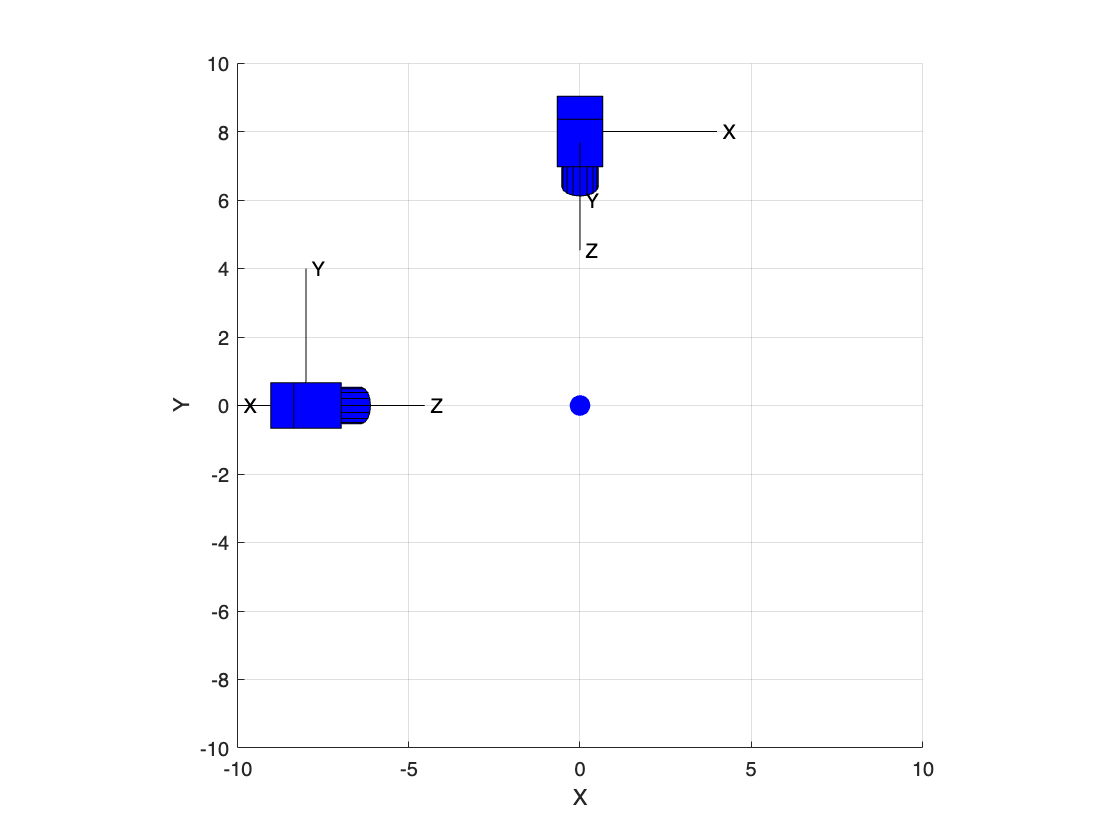

%Project CAMERAS 
f = 0.015; %focal length in meters
np = [640 480]; % number of pixels
pixelsize = 10e-6;

%C1
rotm1 = eul2rotm([0,2*pi/3,0]);
T1 = [rotm1 [-8,0,6]';
     0 0 0 1];
cam1 = CentralCamera('focal', f, 'pixel', pixelsize, 'resolution', np, 'centre', np/2,'pose',T1);

%C2
rotm2 = eul2rotm([0,0,2*pi/3]);
T2 = [rotm2 [0,8,6]';
     0 0 0 1];
cam2 = CentralCamera('focal', f+0.003, 'pixel', pixelsize, 'resolution', np, 'centre', np/2,'pose',T2);

figure, clf, grid, hold on
P = [0 0 0.5]';
plot_sphere(P,0.3)
axis([-10 10 -10 10 0 14])
cam1.plot_camera
cam2.plot_camera

creating new figure for camera


h =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


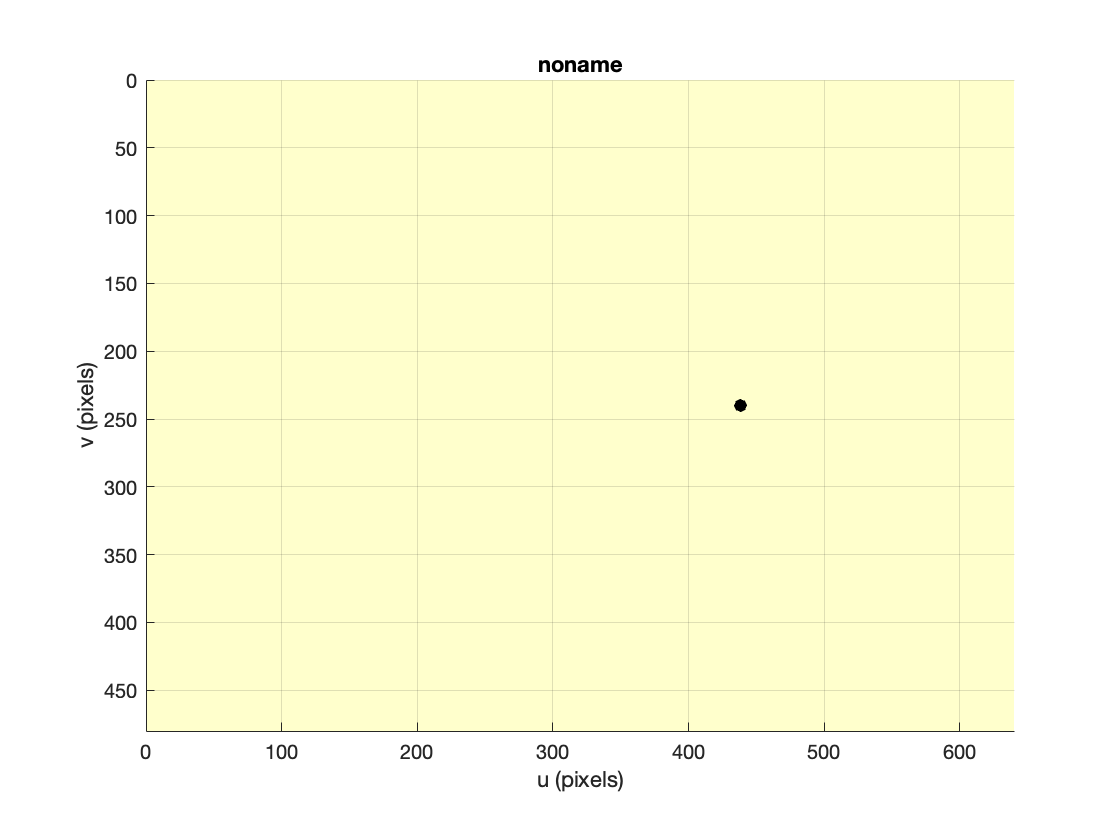


UV1 = cam1.project(P);
cam1.plot(P)

creating new figure for camera


h =   Axes (noname) with properties:

             XLim: [0 640]
             YLim: [0 480]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


make axes


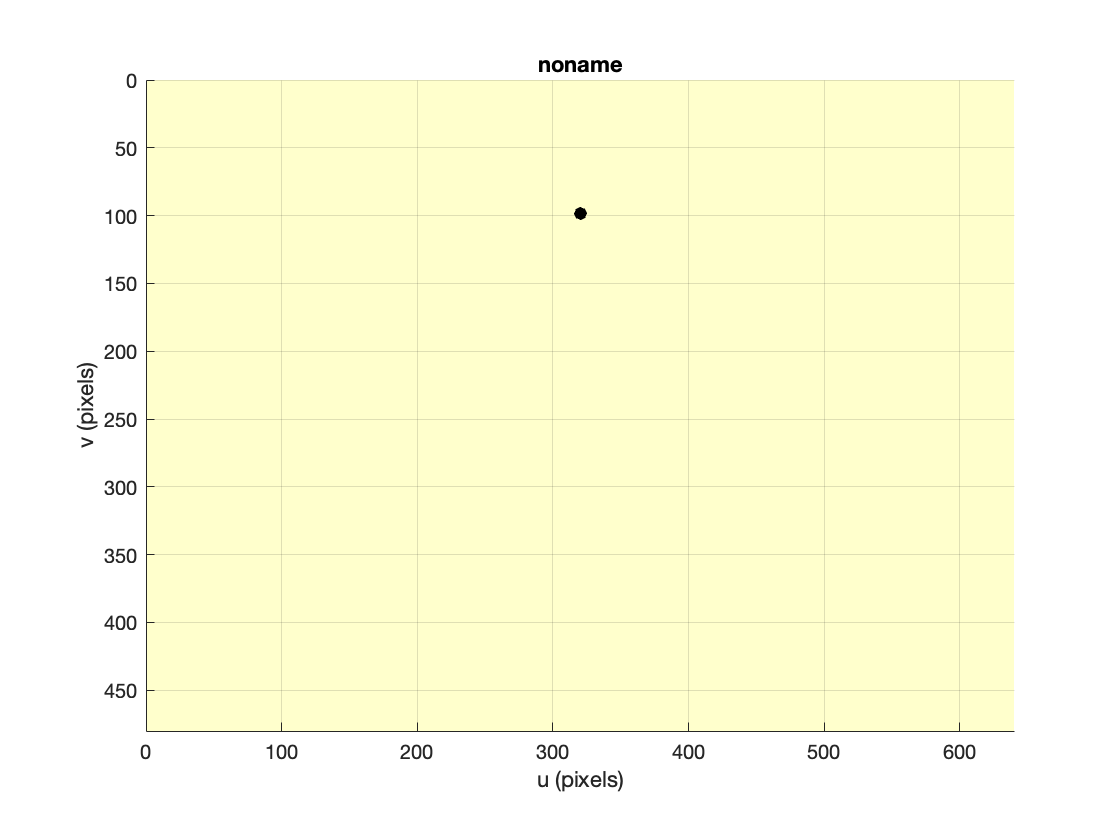

UV2 = cam2.project(P);
cam2.plot(P)


%calculate epipolar lines on cam2 from cam1 projection of P:
K1 = cam1.K;
K2 = cam2.K;
tx_12 = 8;
ty_12 = 8;
tz_12 = 0;
t_12 = [0 -tz_12 ty_12;
        tz_12 0 -tx_12;
        -ty_12 tx_12 0]

t_12 =      0     0     8
     0     0    -8
    -8     8     0



%CHECK
rotm1_2 = rotm2'*rotm1

rotm1_2 =    -0.5000         0    0.8660
   -0.7500   -0.5000   -0.4330
    0.4330   -0.8660    0.2500


EssentMat = t_12 * rotm1_2

EssentMat =     3.4641   -6.9282    2.0000
   -3.4641    6.9282   -2.0000
   -2.0000   -4.0000  -10.3923


FundMat = (eye(3)/K1)' * t_12 * rotm1_2 * (eye(3)/K2)

FundMat =     0.0000   -0.0000    0.0015
   -0.0000    0.0000   -0.0015
   -0.0012   -0.0020   -9.6265




%CHECKING
E = cam1.E(cam2)

E =     6.9282    0.0000    4.0000
   -0.0000   -6.9282    8.0000
    8.0000    4.0000         0


F = cam1.F(cam2)

F =     0.0000    0.0000    0.0014
   -0.0000   -0.0000    0.0051
    0.0045    0.0033   -4.0095




%USING PRE-DET FUNDAMENTAL MATRIX
UV1_H = [UV1;1]

UV1_H =   438.2771
  240.0000
    1.0000



EpipolarLineVariables = UV1_H' * F;
a = EpipolarLineVariables(1)

a = 0.0056

b = EpipolarLineVariables(2)

b = 0.0027

c = EpipolarLineVariables(3)

c = -2.1809


U = linspace(1,np(1),np(1))

U =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


V = -(a/b)*U - c/b

V =   815.7419  813.6280  811.5142  809.4004  807.2866  805.1728  803.0590  800.9452  798.8314  796.7175  794.6037  792.4899  790.3761  788.2623  786.1485  784.0347  781.9209  779.8070  777.6932  775.5794  773.4656  771.3518  769.2380  767.1242  765.0104  762.8965  760.7827  758.6689  756.5551  754.4413  752.3275  750.2137  748.0999  745.9861  743.8722  741.7584  739.6446  737.5308  735.4170  733.3032  731.1894  729.0756  726.9617  724.8479  722.7341  720.6203  718.5065  716.3927  714.2789  712.1651


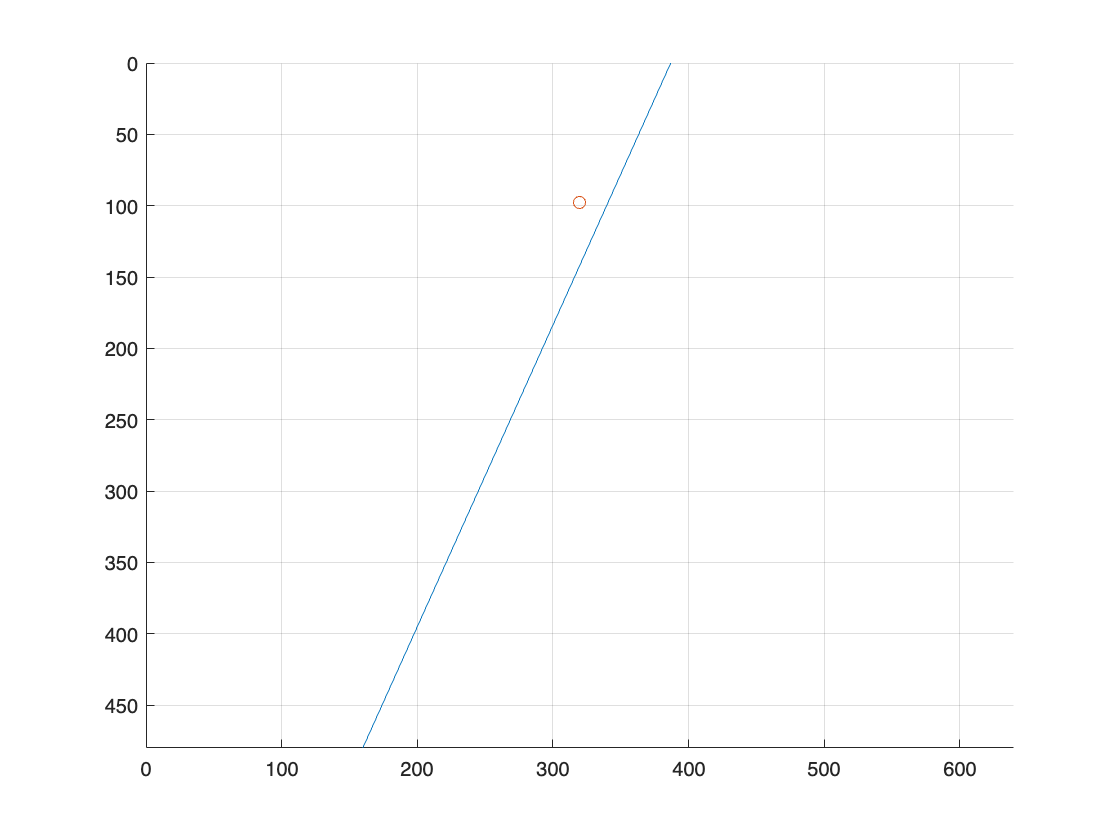


figure,clf,grid,hold on 
plot(U,V);
plot(UV2(1),UV2(2),'o');
set(gca, 'YDir', 'reverse');
axis([0 np(1) 0 np(2)])

%USING PRE-DET ESSETIAL MATRIX
UV1_H = [UV1;1]

UV1_H =   438.2771
  240.0000
    1.0000


F_EMat = (K1^-1)'*E*K2^-1

F_EMat =     0.0000    0.0000    0.0018
   -0.0000   -0.0000    0.0059
    0.0036    0.0028   -3.9739


EpipolarLineVariables = UV1_H' * F_EMat;
a = EpipolarLineVariables(1)

a = 0.0047

b = EpipolarLineVariables(2)

b = 0.0022

c = EpipolarLineVariables(3)

c = -1.7373


U = linspace(1,np(1),np(1))

U =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


V = -(a/b)*U - c/b

V =   779.6348  777.4982  775.3617  773.2251  771.0885  768.9519  766.8154  764.6788  762.5422  760.4056  758.2691  756.1325  753.9959  751.8593  749.7228  747.5862  745.4496  743.3130  741.1765  739.0399  736.9033  734.7667  732.6302  730.4936  728.3570  726.2204  724.0839  721.9473  719.8107  717.6741  715.5376  713.4010  711.2644  709.1278  706.9913  704.8547  702.7181  700.5815  698.4450  696.3084  694.1718  692.0352  689.8987  687.7621  685.6255  683.4889  681.3524  679.2158  677.0792  674.9427


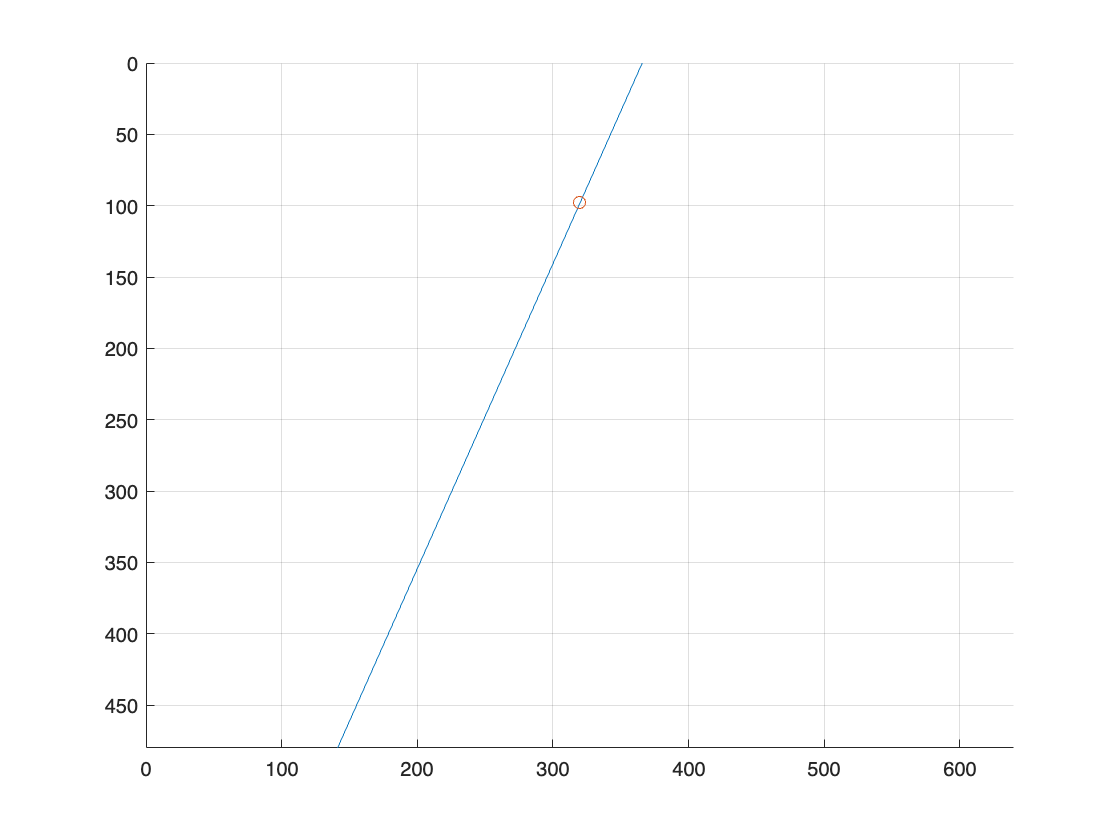


figure,clf,grid,hold on 
plot(U,V);
plot(UV2(1),UV2(2),'o');
set(gca, 'YDir', 'reverse');
axis([0 np(1) 0 np(2)])

%USING PRE-DET POSE of C1 and C2
UV1_H = [UV1;1]

UV1_H =   438.2771
  240.0000
    1.0000



W_R_C1 = rotm1

W_R_C1 =    -0.5000         0    0.8660
         0    1.0000         0
   -0.8660         0   -0.5000


W_R_C2 = rotm2

W_R_C2 =     1.0000         0         0
         0   -0.5000   -0.8660
         0    0.8660   -0.5000


W_t_C1 = [-8,0,6]'

W_t_C1 =     -8
     0
     6


W_t_C2 = [0,8,6]'

W_t_C2 =      0
     8
     6


%C1_t_C2 = C1_R_W'*(C2_t_W-C1_t_W)


C1_t_C2 = W_R_C2'*(W_t_C1-W_t_C2)

C1_t_C2 =    -8.0000
    4.0000
    6.9282


C2_tskew_C1 = [0 -C1_t_C2(3) C1_t_C2(2);
               C1_t_C2(3) 0 -C1_t_C2(1);
               -C1_t_C2(2) C1_t_C2(1) 0;]

C2_tskew_C1 =          0   -6.9282    4.0000
    6.9282         0    8.0000
   -4.0000   -8.0000         0


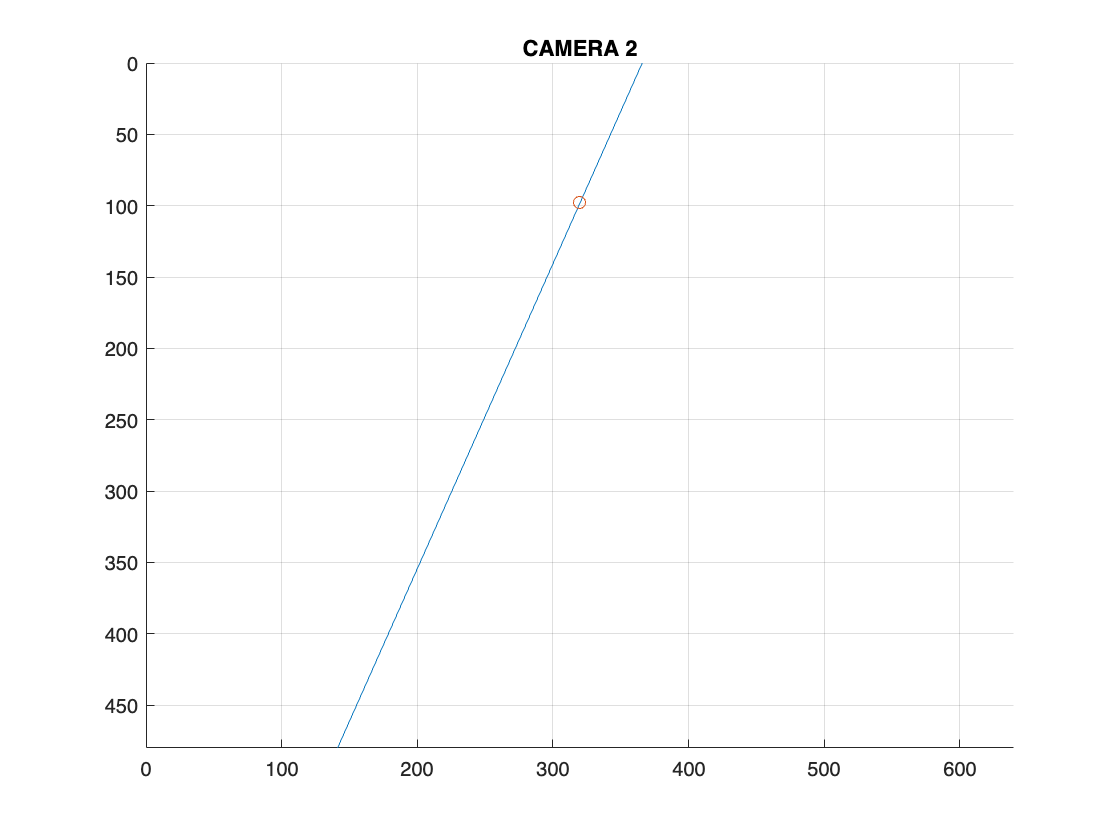


%C1_R_C2 = C1_R_W' * C2_R_W
C2_R_C1 = W_R_C2' * W_R_C1;

E_TEST = C2_tskew_C1*C2_R_C1;

F_EMat = (K1\eye(3))'*E_TEST*(K2\eye(3));
EpipolarLineVariables = UV1_H' * F_EMat;
a = EpipolarLineVariables(1);
b = EpipolarLineVariables(2);
c = EpipolarLineVariables(3);

U = linspace(1,np(1),np(1));
V = -(a/b)*U - c/b;

figure,clf,grid,hold on 
title('CAMERA 2')
plot(U,V);
plot(UV2(1),UV2(2),'o');
set(gca, 'YDir', 'reverse');
axis([0 np(1) 0 np(2)])

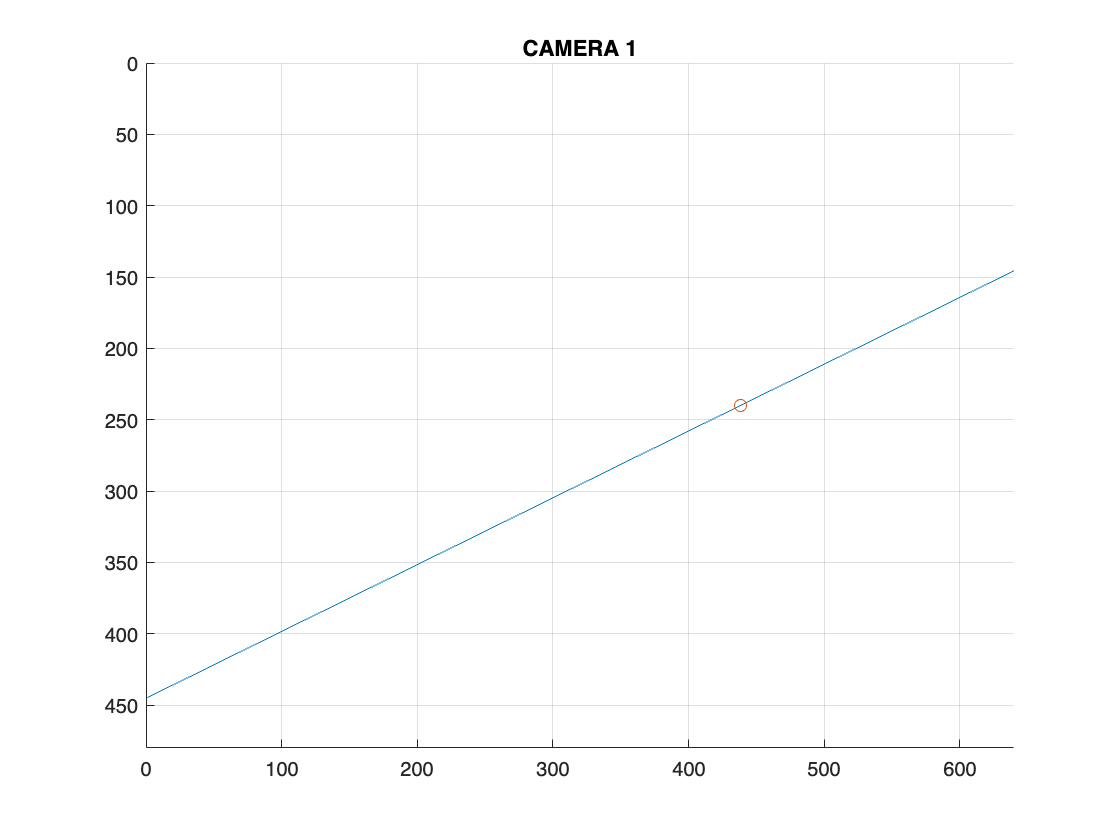


UV2_H = [UV2;1];
F_EMat2 = F_EMat';
EpipolarLineVariables = UV2_H' * F_EMat2;
a = EpipolarLineVariables(1);
b = EpipolarLineVariables(2);
c = EpipolarLineVariables(3);

U = linspace(1,np(1),np(1));
V = -(a/b)*U - c/b;

figure,clf,grid,hold on 
title('CAMERA 1')
plot(U,V);
plot(UV1(1),UV1(2),'o');
set(gca, 'YDir', 'reverse');
axis([0 np(1) 0 np(2)])